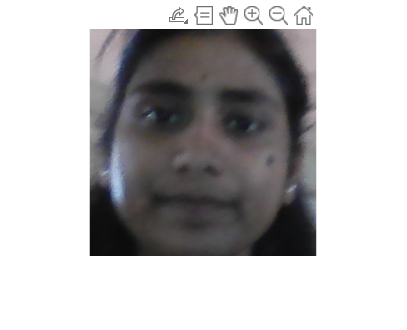

clc
clear all
close all
warning off;
cao=webcam;
faceDetector=vision.CascadeObjectDetector;
c=150;
temp=0;
while true
    e=cao.snapshot;
    bboxes =step(faceDetector,e);
    if(sum(sum(bboxes))~=0)
    if(temp>=c)
        break;
    else
    es=imcrop(e,bboxes(1,:));
    es=imresize(es,[227 227]);
    filename=strcat(num2str(temp),'.bmp');
    imwrite(es,filename);
    temp=temp+1;
    imshow(es);
    drawnow;
    end
    else
        imshow(e);
        drawnow;
    end
end